# MATLAB: Datatypes and Arrays

MATLAB deals with arrays (matrices) of any type efficiently. This is its competitive advantage. To take advantage of this, you need to understand how to deal with the arrays in MATLAB.

## Data Types in MATLAB

There are many types of data in MATLAB. Each data type can be manipulated in unique ways using a variety of functions

### Numeric types

- `Double` - double precision arrays

- `Single` - single precision arrays

- `int8` / `uint8` - 8 bit integers

- `int16` / `uint16` - 16 bit integers

- `int32` / `uint32` - 32 bit integers

- `int64` / `uint64` - 64 bit integers

### Text types

- `char` - array of elements that must contain the same number of characters 

- `strings` - array of elements that contain any number of characters

### Other types

- `Date and Time`

- `Tables`

- `Structures`

- `Cell arrays`

- `Function Handles`

## Things to keep in mind

In MATLAB, everything is an array

- numeric arrays

- logical arrays

- character arrays

- string arrays

- cell arrays

With numeric arrays, standard operators (`+|-|*|/`) take on different meanings when preceded by a `'.'. T`he `'.'` indicates 'element by element' operations

## Numeric Arrays: Indexing

Numeric Arrays refer to vectors and any higher dimensional matrices. There are two ways of referencing an array

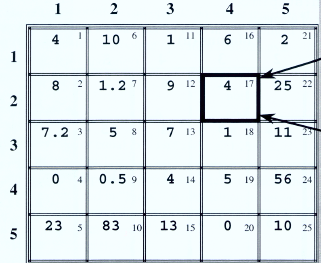

- 2+ indices: specify row and column, ...

a=magic(4)

a =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


a(2,3)

ans =     10

- 1 index: runs down each column

a(11)

ans =      6

## Numeric Arrays: Creating

Array elements must be enclosed by` […]`. Columns are separated by a `<space>` or` ,` and rows are separated by a `;`

A = [1,2 3;4 5 ,6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


MATLAB has a very special operator `':'. This s`aves typing when creating a numeric array

A = 1:9

A =      1     2     3     4     5     6     7     8     9


B = 1:3:9

B =      1     4     7


C=1:0.2:9

C =    1.000000000000000   1.200000000000000   1.400000000000000   1.600000000000000   1.800000000000000   2.000000000000000   2.200000000000000   2.400000000000000   2.600000000000000   2.800000000000000   3.000000000000000   3.200000000000000   3.400000000000000   3.600000000000000   3.800000000000000   4.000000000000000   4.200000000000000   4.400000000000000   4.600000000000000   4.800000000000001   5.000000000000000   5.199999999999999   5.400000000000000   5.600000000000000   5.800000000000000   6.000000000000000   6.199999999999999   6.400000000000000   6.600000000000000   6.800000000000000   7.000000000000000   7.200000000000000   7.400000000000000   7.600000000000000   7.800000000000000   8.000000000000000   8.199999999999999   8.400000000000000   8.600000000000000   8.800000000000001   9.000000000000000


A = reshape(A,3,3)

A =      1     4     7
     2     5     8
     3     6     9


A'

ans =      1     2     3
     4     5     6
     7     8     9


## Numeric Arrays: Combining

MATLAB makes it easy to combine (or concatenate) arrays, just make sure the dimensions work out.

B = [1,3,7]

B =      1     3     7


C = [A; B]

C =      1     4     7
     2     5     8
     3     6     9
     1     3     7


C = [A B']

C =      1     4     7     1
     2     5     8     3
     3     6     9     7


## Numeric Arrays: Operations

MATLAB can operate element by element or matrix-wise depending on the syntax

What does … give?

A*A

ans =     30    66   102
    36    81   126
    42    96   150


A.*A

ans =      1    16    49
     4    25    64
     9    36    81


A*B'

ans =     62
    73
    84


A.*B'

ans =      1     4     7
     6    15    24
    21    42    63


## Character and String Arrays

These arrays operate in the same manner as numeric arrays, just with different data types, characters. You can index into, reshape, and concatenate string arrays using standard array operations, and you can append text to strings using the + operator

Type `doc` `string` for more info 

Character arrays are arrays of single elements

char1 = 'kelley'

char1 = 'kelley'

char1'

ans = 6×1 char array
    'k'
    'e'
    'l'
    'l'
    'e'
    'y'

char1(3)

ans = 'l'

char2 = ['k','e','l','l','e','y']

char2 = 'kelley'

Can concatenate them?

char3 = 'tom'

char3 = 'tom'

%char13 = char1+char3

Oooo, maybe not!

char12 = char1+char2

char12 =    214   202   216   216   202   242


char(char12)

ans = 'ÖÊØØÊò'

How are we suppose to deal with long strings of text? Well, with a string array - 

str1 = "kelley"

str1 = "kelley"

str2 = ["k1", "e", "l","l","e","y"]

str2 = 1×6 string array
    "k1"    "e"    "l"    "l"    "e"    "y"

class(str2(3))

ans = 'string'

str12 = str1+str2

str12 = 1×6 string array
    "kelleyk1"    "kelleye"    "kelleyl"    "kelleyl"    "kelleye"    "kelleyy"

str3 = [str1; "string of a totally different length"]

str3 = 2×1 string array
    "kelley"
    "string of a totally different length"

## Cell Arrays

A cell array is a data type with indexed data containers called cells. Each *cell* can contain any type of data,

C = {1,2,3;'one', 'two',"three"}

When using cell arrays remember:

- Use {} to reference the values within the cell array

- Use () to get a sub-”cell” array

- Cell arrays are flexible, but sometimes are difficult to work with

element1 = C{2,3}
cell1 = C(2,3)

## Logical Arrays

Do you want to know if two numeric/string arrays are the same? Well, the result will be stored as a logical array

array1 = [2.34,3.56,-4.56,9.78];
array2= [2.34,-5.87,0.567,9.78];
array1==array2

ans = 1×4 logical array
   1   0   0   1


array1>array2

ans = 1×4 logical array
   0   1   0   0


str1="How now brown cow?";
str2="how now brown Cow?";
char1='how now brown cow';
char2 = 'how now brown cow';
str1==str2

ans = logical
   0

lower(str1)==lower(str2)

ans = logical
   1

char1==char2

ans = 1×17 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


str1==char1

ans = logical
   0

You can string together logical statements using & (and) and | (or).

Logical Arrays can be used to index an array. The logical array must be the same size as the indexed array. When indexed in this way, the program will only print/store values that correspond to a true value in the logical array

x =1:2:30

x =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29


x<6

ans = 1×15 logical array
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0


x<3 & x>27 | x<100

ans = 1×15 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


xfilter = x(x<3 | x>27)

xfilter =      1    29


## Useful Functions

A = [1,3,5;-1,8,9;-4,5,-2;1,1,5]
B = 2:0.5:9

Number of elements

numel(A)
numel(B)

Size of array

size(A)
size(B)

Length of Array

length(A)
length(B)
B(B~=3|B>7)